## DFT of the signal

#### Generate the matrix B


$$B=b_{k\ell} = e^{2\pi j k\frac{\ell}{n}}, \quad k,\ell = 0,\ldots,n-1$$


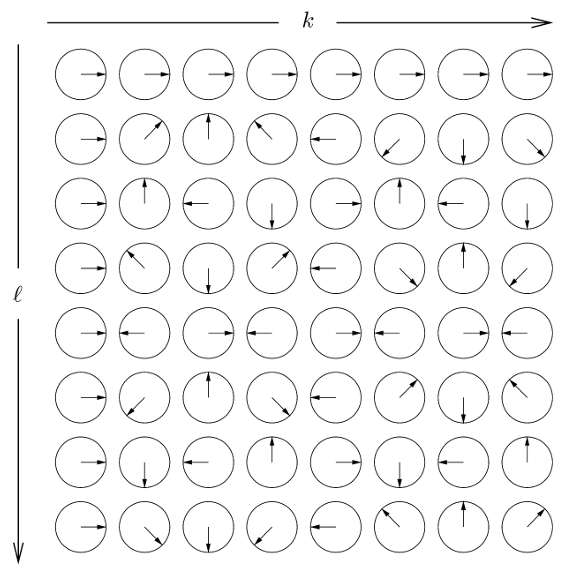

#### Original calculation of Matrix B

% B = zeros(N, N);
% for k = 0:N-1
%     for l = 0:N-1
%         B(k+1, l+1) = exp(2*pi*1i*k*l/N);
%     end
% end
% time_DFT = tic ;

#### Script check:

B∗ the adjoint matrix of B, i.e. the

matrix which is obtained by transposition of B and the complex conjugate of

all components

If we do that B_transposed and_conj == B

% % B_transposed_conj = zeros(N, N);
% % for k = 0:N-1
% %     for l = 0:N-1
% %         B_transposed_conj(l+1, k+1) = conj(exp(2*pi*1i*k*l/N));
% %     end
% % end

#### Calculate the DFT


$$\text{DFT}(\vec{f})= \vec{z} = B^{-1} \vec{f} $$



$$B^{-1} = \frac{1}{n}  B^*$$



$$\text{DFT}(\vec{f}) = \vec{z} = \frac{1}{n}  B^* \vec{f}$$


%DFT_signal_1 = (1/N) * B * h1(:);
%DFT_signal_2 = (1/N) * B * h2(:);

#### Splitting B up due to size issues

time_DFT = tic;
N = length(h1);

DFT_signal_1 = zeros(N, 1);
DFT_signal_2 = zeros(N, 1);

for k = 0:N-1
    B_row = exp(-2*pi*1i*k*(0:N-1)/N);                 % Generate only the current used row
    DFT_signal_1(k+1) = (1/N) * sum(B_row .* h1(:).');
    DFT_signal_2(k+1) = (1/N) * sum(B_row .* h2(:).');
end
time_DFT = toc(time_DFT)

time_DFT = 89.4309

#### Cyclic shift


$$ F_k e^{-2 \pi j k \frac{m}{n}}$$


cyclic shift by m places

shifted_DFT_signal_1 = zeros(size(DFT_signal_1));
shifted_DFT_signal_2 = zeros(size(DFT_signal_2));

for k = 0:N-1
    n = mod(k + N/2, N);
    shifted_DFT_signal_1(n+1) = DFT_signal_1(k+1)*exp(-1i*pi*k);
    shifted_DFT_signal_2(n+1) = DFT_signal_2(k+1)*exp(-1i*pi*k);
end

% Amplitudespectrum
shifted_DFT_signal_1_magnitude = abs(shifted_DFT_signal_1);
shifted_DFT_signal_2_magnitude = abs(shifted_DFT_signal_2);

% Frequency axis
k=1:N;                                
f=(k-1)*(1/(N*ts));                           
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));       

#### Plot the DFT

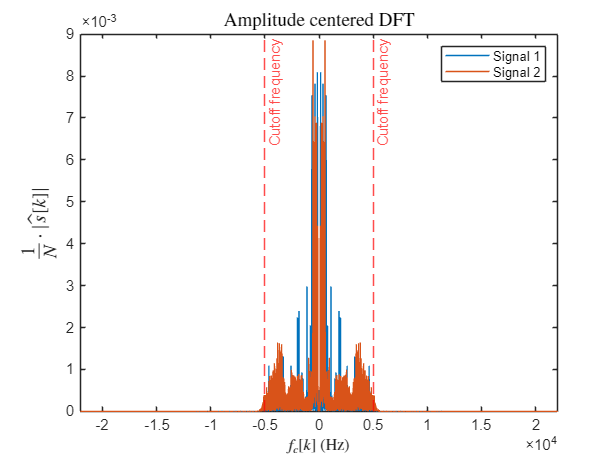

figure()
plot(f_c,shifted_DFT_signal_1_magnitude)
hold on
plot(f_c,shifted_DFT_signal_2_magnitude)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
legend('Signal 1','Signal 2')
title('Amplitude centered DFT','Interpreter','Latex', 'FontSize', 13)
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
xlim([min(f_c) max(f_c)])

#### Calculate the iDFT


$$\text{iDFT}(\vec{z}) = \vec{f} = B \vec{z}$$


% iDFT_signal_1 = B * DFT_signal_1;
% iDFT_signal_2 = B * DFT_signal_2;

iDFT_signal_1 = zeros(N, 1);
iDFT_signal_2 = zeros(N, 1);


for n = 0:N-1
    B_row = exp(2*pi*1i*n*(0:N-1)/N);
    iDFT_signal_1(n+1) = sum(B_row .* DFT_signal_1(:).'); 
    iDFT_signal_2(n+1) = sum(B_row .* DFT_signal_2(:).'); 
end

#### Plot the iDFT and compare with the lowpassfiltered signal

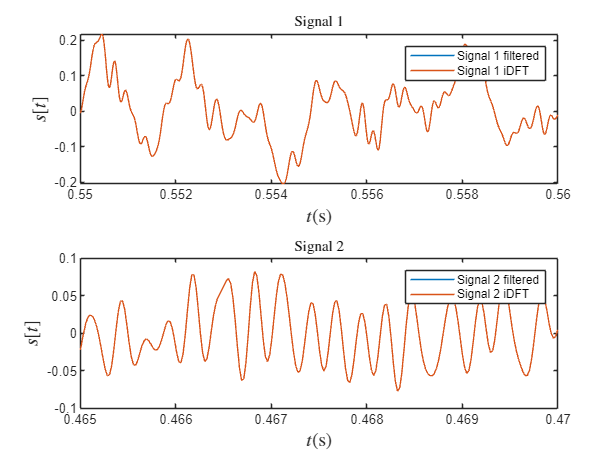

figure()
tiledlayout(2,1);
nexttile
plot(t,h1)
hold on
plot(t,real(iDFT_signal_1))
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 filtered','Signal 1 iDFT')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t,h2)
hold on
plot(t,real(iDFT_signal_2))
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 filtered','Signal 2 iDFT')
xlim([0.465 0.47])%xlim([0 max(t)])

disp(['Comparison lowpassfiltered signal 1 and iDFT signal 1 // Difference = ' num2str(sum(h1'-real(iDFT_signal_1)))])

Comparison lowpassfiltered signal 1 and iDFT signal 1 // Difference = -9.1329e-11


disp(['Comparison lowpassfiltered signal 2 and iDFT signal 2 // Difference = ' num2str(sum(h2'-real(iDFT_signal_2)))])

Comparison lowpassfiltered signal 2 and iDFT signal 2 // Difference = -1.3131e-10


## Comparison with the Matlab calculated FFT

(Check if our filtering works properly)

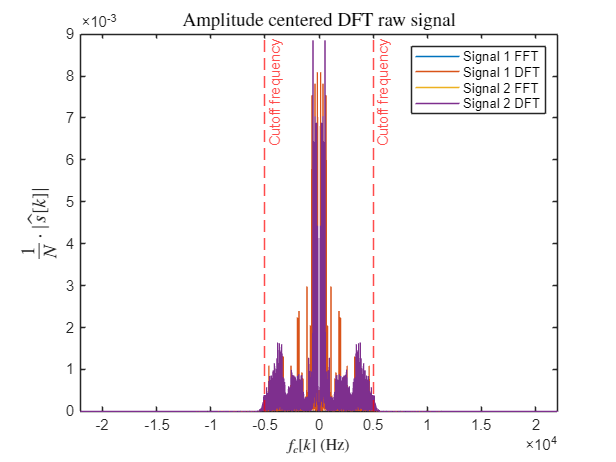

FFT_signal_1_Matlab = fft(h1);
FFT_signal_2_Matlab = fft(h2);

FFT_signal_1_shift_Matlab = fftshift(FFT_signal_1_Matlab);
FFT_signal_2_shift_Matlab = fftshift(FFT_signal_2_Matlab);

FFT_signal_1_ampl_Matlab = 1/N*abs(FFT_signal_1_shift_Matlab);
FFT_signal_2_ampl_Matlab = 1/N*abs(FFT_signal_2_shift_Matlab);      

k=1:N;                                          
f=(k-1)*(1/(N*ts));                              
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));              

figure()
plot(f_c,FFT_signal_1_ampl_Matlab)                    
hold on
plot(f_c,shifted_DFT_signal_1_magnitude)
plot(f_c,FFT_signal_2_ampl_Matlab) 
plot(f_c,shifted_DFT_signal_2_magnitude)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered DFT raw signal','Interpreter','Latex', 'FontSize', 13)
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('Signal 1 FFT','Signal 1 DFT','Signal 2 FFT','Signal 2 DFT')
xlim([min(f_c) max(f_c)])